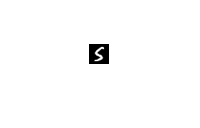

clear;
load('data1.mat');
Y = (1:10) == y;

%open neural network pattern recognition from apps 
% In the Welcome page, read the information about the pattern recognition network uses and structure, then click Next.
% In the Select Data page, select X from the Inputs list, select Y from the Targets list, and select 'Matrix rows' for the sample orientation, then click 'Next'.
% In the Validation and Test Data page, select 5% for 'Validation' and 'Testing' and click 'Next'.

%In the Network Architecture page, enter '25' for the 'Number of Hidden Neurons' and click 'Next'.
%In the Train Network page, click the 'Train' button. The Neural Network Training Tool app will automatically open and train network. When the training is finished, several plots are available for inspection which provide information on the training and performance of the network model in the 'Plots' section of the Neural Network Training Tool.
%Close the Neural Network Training Tool, return to the Pattern Recognition App, and click 'Next'.

%evaluate network
%Since the performance is satisfactory (and we have no additional data) click 'Next'.
%In the Deploy Solution page, available options are shown for deploying the network. Click 'Next' to skip deployment. 
%In the Save Results page, click the 'Simple Script' button in the 'Generate Scripts' section to generate a script for recreating and training the network in the future. Inspect the script and discard it when you are done.
%Select the 'Save network to MATLAB Object named:' checkbox in the 'Save Data to Workspace' section and de-select the other boxes
%Enter the network variable name, 'net', in the corresponding box, then click the 'Save Results' button to export the neural network variable to the workspace.
%Click the 'Finish' button to exit the Pattern Recognition App and close the Neural Network Start App.


i = randi(length(y));
ysim = net(X(i,:)');
[~,class] = max(ysim);
imshow(reshape(X(i,:),20,20))

fprintf('True class: %d  |  Predicted class: %d | Probability of match: %.1f%%',y(i),class,100*ysim(class));

True class: 5  |  Predicted class: 5 | Probability of match: 97.7%



%Train a custom network with regularization

% Change lambda and MaxIter to see how it affects the result
lambda = 0.01;
MaxIter = 90;
net = imageNet(X,Y,lambda,MaxIter);
[~,ysim] = max(net(X'));
fprintf('Training accuracy: %g%%',100*sum(y == ysim')/length(y));

Training accuracy: 99.18%

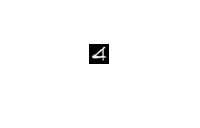


i = randi(length(y));
ysim = net(X(i,:)');
[~,class] = max(ysim);
imshow(reshape(X(i,:),20,20))

fprintf('True class: %d  |  Predicted class: %d | Probability of match: %.1f%%',y(i),class,100*ysim(class));

True class: 4  |  Predicted class: 4 | Probability of match: 64.8%

function net = imageNet(X,Y,lambda,MaxIter) 
% Build, train, and return a neural network model to classify the 1x400 images
% of digits in X with labels in Y

% MATLAB neural networks prefer examples in columns and labels in rows
X = X';
Y = Y';

% Set network options:
hiddenLayerSize = 25; % Create a neural net with a single hidden layer with 25 output neurons
trainFcn = 'trainscg';  % Use scaled conjugate gradient backpropagation
net = patternnet(hiddenLayerSize, trainFcn); % Create the net variable
net.layers{1}.transferFcn = 'logsig'; % Change default transfer function to match ex3/4 implementation

% Add regularization: 
% Note that the MATLAB regularization parameter must lie between 0 and 1,
% where 0 correspnds to lambda = 0 (no regularization) and 1 corresponds to lambda = inf. 
% We map the input lambda value to [0,1] using tanh function
net.performParam.regularization = tanh(lambda);  
net.trainParam.epochs = MaxIter;
net.trainParam.showWindow = false; % Don't show training GUI

% Setup Division of Data for Training, Validation, Testing 
% This example uses all of the data for training (to match ex3/ex4 network example)
% Validation and test data is discussed later in the course
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 0/100;

% Train the Network
net = train(net,X,Y);
end